### 使用嵌套函数的技术编写一个GUI程序

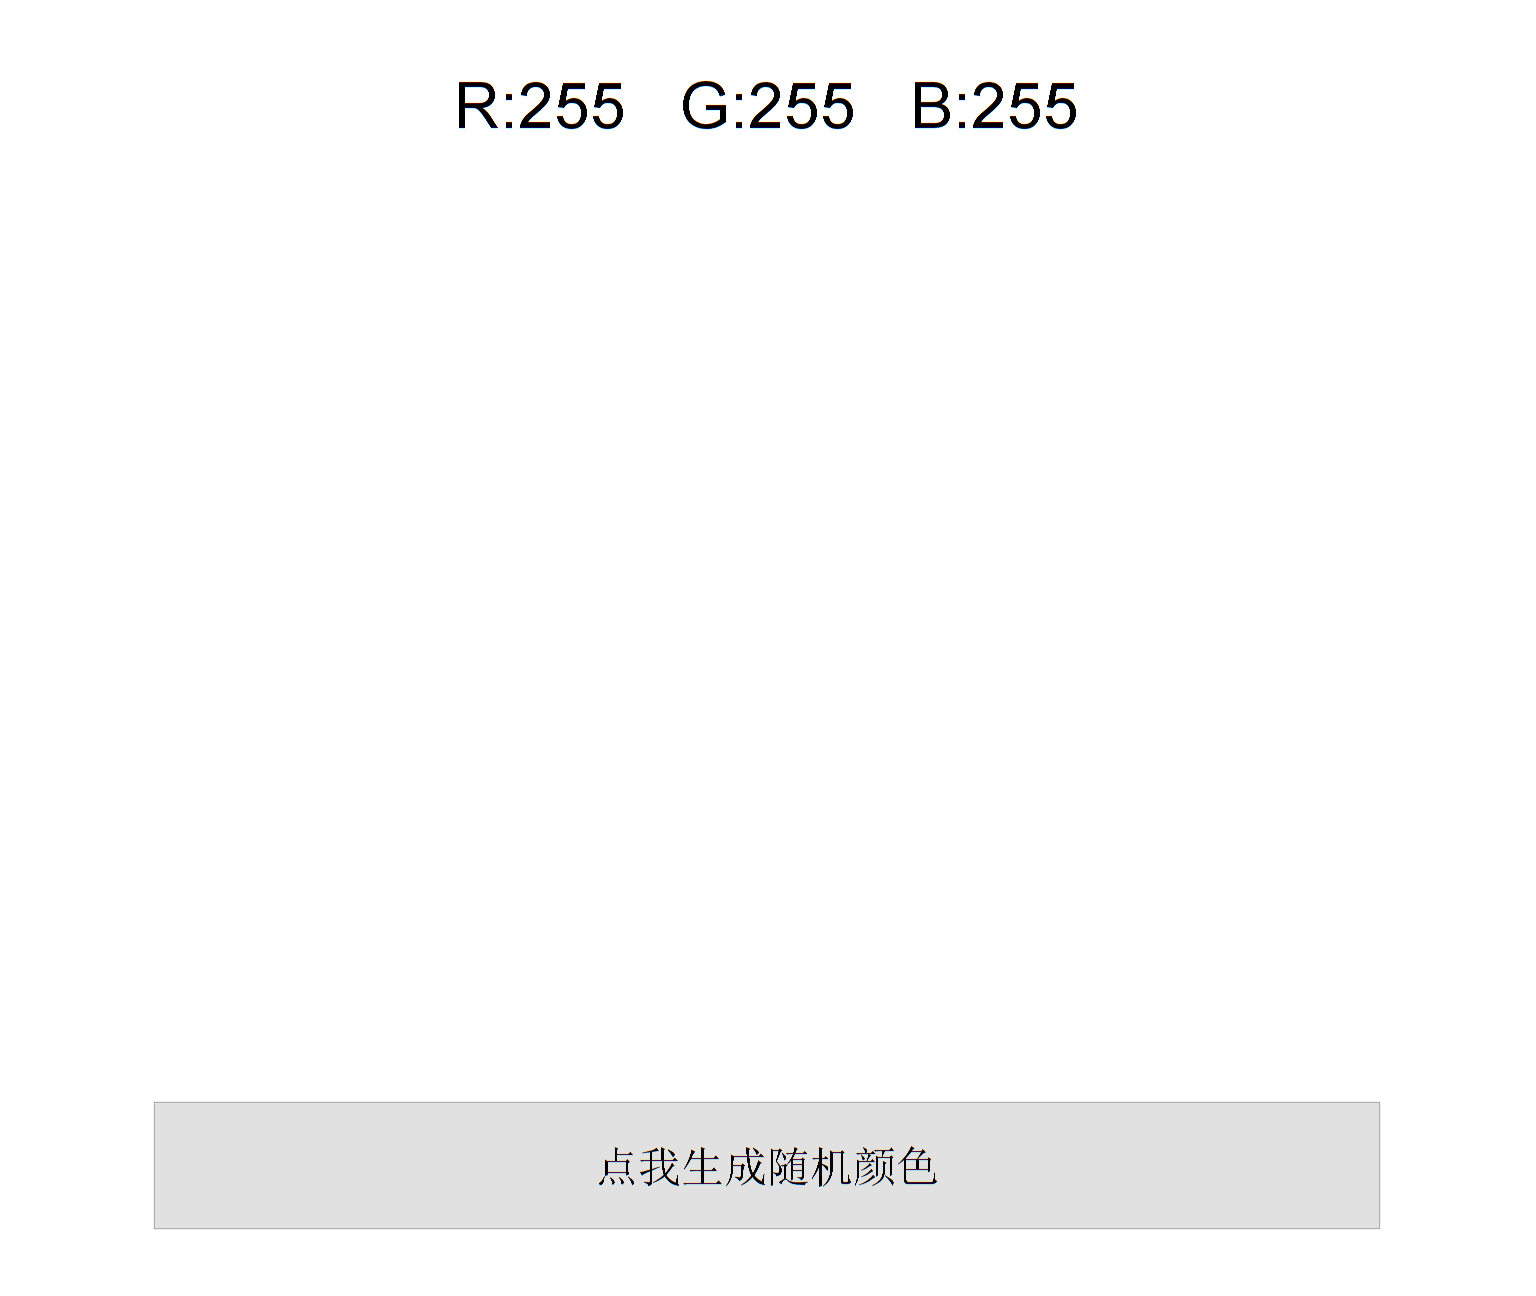

GUI_color

（我更推荐大家学习APPdesigner，这个才是MATLAB发展的趋势，GUI未来可能会被MATLAB淘汰）

APPdesigner是面向对象编程，建议先了解下MATLAB中如何创建和实例化一个类，里面会学到新的关键字classdef

function GUI_color()  
    f = figure;
    f.Units = 'normalized';
    f.Position = [0.3 0.2 0.4 0.6];  % 指定为[left bottom width height] 形式的向量
    f.MenuBar = 'none'; % 去掉菜单栏
    f.Color = [1 1 1];  % 背景颜色为白色
    f.NumberTitle = 'off';  % 关闭带编号的标题
    f.Name = '第一个GUI应用';
    ax = axes(f,'Position',[0.17 0.2 0.66 0.66]);
    % 生成一个按钮
    uicontrol(f, 'Style','pushbutton','String','点我生成随机颜色', ...
        'FontSize',16,'Units','normalized','Position',[0.1 0.05 0.8 0.1], ...名称-值参数Position和Units的位置不能交换
        'Callback', @change_color);  % 回调函数：随机生成颜色
    % 生成一个文本段用于显示当前RGB
    t = uicontrol(f, 'Style','text','String','R:255   G:255   B:255', ...
        'FontSize',24,'Units','normalized','Position',[0.1 0.85 0.8 0.1], ...
        'BackgroundColor',[1 1 1]);
    im = ones(1,1,3);  % 初始颜色，全白色的图片
    imshow(im,'Parent',ax)
        function change_color(~,~)
            im = rand(1,1,3);
            imshow(im,'Parent',ax)
            change_text
        end
        function change_text
            q = round(im*255);
            c = sprintf('R:%03d   G:%03d   B:%03d',q(1),q(2),q(3));
            t.String = c;
        end
end



以下内容来自文心一言4：

这是一个MATLAB函数，用于创建一个图形用户界面(GUI)，其中包含一个按钮和一个文本显示。当用户点击按钮时，会显示一个随机生成的颜色，并且文本显示会更新为当前颜色的RGB值。以下是对该函数的详细解释：

**（1）函数定义**:

`function` `GUI_color``()`

定义了一个名为`GUI_color`的函数。

**（2）创建图形窗口**:

`f = ``figure``;`

使用`figure`函数创建一个新的图形窗口，并将其句柄赋值给变量`f`。

**（3）设置图形窗口的属性**:

接下来的几行代码设置了图形窗口的各种属性，如位置、背景颜色、是否显示菜单栏等。

**（4）添加坐标轴**:

`ax = axes(f,``'Position'``,[``0.17` `0.2` `0.66` `0.66``]);`

在图形窗口中添加一个坐标轴，并设置其位置。这个坐标轴将用于显示图像。

**（5）创建一个按钮**:

使用`uicontrol`函数创建一个按钮，并设置了其各种属性，如样式、字体大小、位置和回调函数等。当用户点击这个按钮时，会调用`change_color`函数。

**（6）创建一个文本显示**:

再次使用`uicontrol`函数创建一个文本显示，用于展示当前的RGB颜色值。初始值设置为白色（R:255 G:255 B:255）。

**（7）显示初始图像**:

使用`imshow`函数在坐标轴上显示一个全白色的图像。这里，图像只是一个1x1x3的矩阵，表示一个白色像素。

**（8）定义回调函数**`change_color`:

当用户点击按钮时，这个函数会被调用。函数内部首先生成一个随机的RGB颜色值，并使用`imshow`函数在坐标轴上显示这个颜色。然后，它调用`change_text`函数来更新文本显示的内容。

**（9）定义函数**`change_text`:

这个函数用于更新文本显示的内容，以反映当前显示的颜色的RGB值。它首先将RGB值从[0,1]范围缩放到[0,255]范围，并使用`sprintf`函数格式化字符串，然后更新文本显示的内容。

**注意**:  在MATLAB的GUI编程中，`uicontrol`函数用于创建用户界面控件，如按钮、文本框等。`Callback`属性用于指定当用户与控件交互时要执行的函数。在这个例子中，当用户点击按钮时，会执行`change_color`函数。

另外，值得注意的是，嵌套函数（如`change_color`和`change_text`）可以访问其父函数（在这里是`GUI_color`）的变量，这就是为什么`change_color`和`change_text`可以直接访问和修改`ax`和`t`等变量的原因。

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1Xm41167aC/](https://www.bilibili.com/video/BV1Xm41167aC/)